# Plots

clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Qband spectrum with lines at g = 2.003 and g = 2.0065

gm_07_20230622_fit

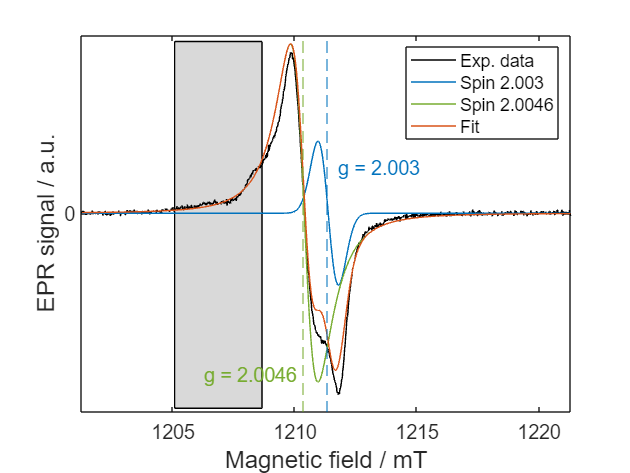

load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
load('data/processed/gm20230622_sample4_Qband_mwpw_18dB_fit.mat');
load("ColorsPlot.mat");
ICW = 5;
x = cw(ICW).x;
y = -real(cw(ICW).y2);

figure()
plot(x, y, 'Color', PlotColors(1), 'DisplayName', 'Exp. data')
hold on
plot(x, Fit.fit, 'Color', PlotColors(2), 'DisplayName', 'Fit')
plot(x, Fit.yFit0, 'Color',  PlotColors(3),  'DisplayName', 'Spin 2.0046')
plot(x, Fit.yFit1, 'Color',  PlotColors(4), 'DisplayName', 'Spin 2.003')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.0046), '--', 'Color', PlotColors(3), 'HandleVisibility', 'off')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.003), '--', 'Color', PlotColors(4), 'HandleVisibility', 'off')
rectangle('position', [x(195) -25 (x(378) - x(195)) 47], 'FaceColor', [.85 .85 .85])

Label = "g = 2.0046";
text(0.25, 0.1, Label, 'Units', 'normalized', ...
    'FontSize', 13, 'Color', PlotColors(3));
Label = "g = 2.003";
text(0.525, 0.65, Label, 'Units', 'normalized', ...
'FontSize', 13, 'Color', PlotColors(4));

chH = get(gca, "Children");
set(gca,'Children',[chH(6);chH(5);chH(4);chH(7);chH(3);chH(2);chH(1)])

ylim(setAxLim(y, 0.05))
xlim(setAxLim(x, 0))
yticks(0)
legend()
labelAxesFig(gca, "Magnetic field / mT", "EPR signal / a.u.")
% exportFig(gcf, 'images', 'sijia-fig-00001', '.svg')

## X-band and Q-band plotted on a g-value axis

X-band: gm_09_20230720_dataPreparation,

Q-band: gm_06_20230622_dataPreparation

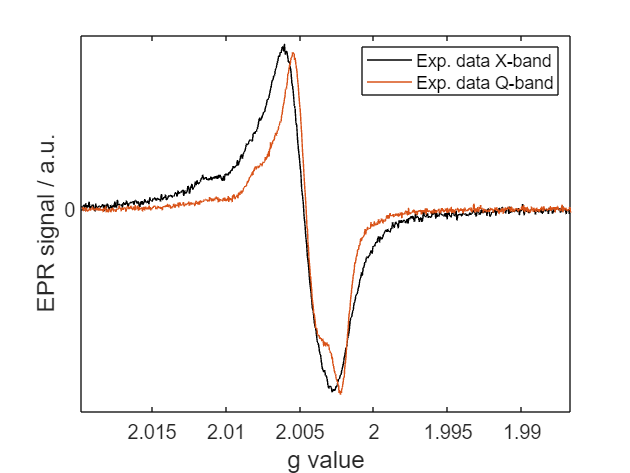

load('data/processed/gm20230720_sample4.mat');
cwX = cw;
load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
cwQ = cw(5);
load("ColorsPlot.mat");

gaxX = planck*cwX.Params.MWFQ/bmagn./(cwX.x/1000);
gaxQ = planck*cwQ.Params.MWFQ/bmagn./(cwQ.x/1000);
% figure()
% tiledlayout('flow', 'TileSpacing', 'tight', 'Padding', 'tight')
% nexttile
% plot(cwX.x, cwX.y)
% xlim(setAxLim(cwX.x, 0))
% ylim(setAxLim(cwX.y, 0.05))
% nexttile
% plot(gaxX, cwX.y)
% xlim(setAxLim(gaxX, 0))
% ylim(setAxLim(cwX.y, 0.05))
% set(gca, 'Xdir', 'reverse')
% nexttile
% plot(cwQ.x, cwQ.y)
% xlim(setAxLim(cwQ.x, 0))
% ylim(setAxLim(cwQ.y, 0.05))
% nexttile
% plot(gaxQ, cwQ.y)
% xlim(setAxLim(gaxQ, 0))
% ylim(setAxLim(cwQ.y, 0.05))
% set(gca, 'Xdir', 'reverse')
figure()

plot(gaxX, rescaledata(cwX.y, cwQ.y, 'lsq'), 'Color', PlotColors(1), 'DisplayName', 'Exp. data X-band')
hold on
plot(gaxQ, cwQ.y, 'Color', PlotColors(2), 'DisplayName', 'Exp. data Q-band')

set(gca, 'Xdir', 'reverse')
ylim(setAxLim(cwQ.y, 0.05))
xlim(setAxLim(gaxQ, 0))
yticks(0)
legend()
labelAxesFig(gca, "g value", "EPR signal / a.u.")

% exportFig(gcf, 'images', 'sijia-fig-00002', '.svg')

# Comparison between X-band spectra of sample 4 in a Q-band tube and sample 1b in an X-band tube

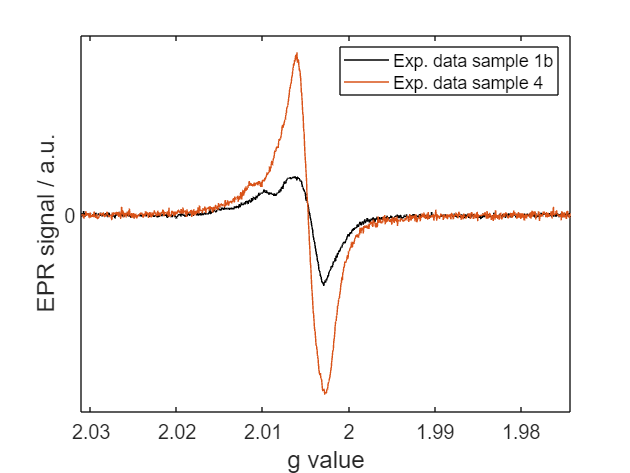

load('data/processed/gm20230720_sample4.mat');
cw4 = cw;
load('data/processed/gm20230804_sample1b.mat');
cw1b = cw;
load("ColorsPlot.mat");

gax4 = planck*cw4.Params.MWFQ/bmagn./(cw4.x/1000);
gax1b = planck*cw1b.Params.MWFQ/bmagn./(cw1b.x/1000);

figure()
plot(gax1b, cw1b.y, 'Color', PlotColors(1), 'DisplayName', 'Exp. data sample 1b')
hold on
plot(gax4, cw4.y, 'Color', PlotColors(2), 'DisplayName', 'Exp. data sample 4')

set(gca, 'Xdir', 'reverse')
ylim(setAxLim(cw4.y, 0.05))
xlim(setAxLim(gax4, 0))
yticks(0)
legend()
labelAxesFig(gca, "g value", "EPR signal / a.u.")
% exportFig(gcf, 'images', 'sijia-fig-00003', '.svg')